## 创建者：林宸曳LuCkY，2025RM，平步电控

## 一、说明

    这份代码根据上交的那份平步开源建模（上海交通大学RoboMaster2023平衡步兵控制系统开源）写成。

    1、简化平步为机体、左右腿、左右驱动轮5部分，且质量分布均匀。

    2、忽略腿部、机体位形变化对z轴转动惯量影响，绕z轴的转动惯量简化为常量。

    3、假设驱动轮与地面无滑动（后续加入离地/打滑检测）

    4、假设roll（滚转角度）为0，其1导、2导也为0

    5、假设左右腿支持力相等

    6、自然坐标系

% 实际机器人腿部为五连杆机构，腿长可变，长度由腿部电机控制。质心位置、转动惯量均随腿长变化。

## 二、变量与参数的定义

    单位为m、kg。

###     1、变量的定义

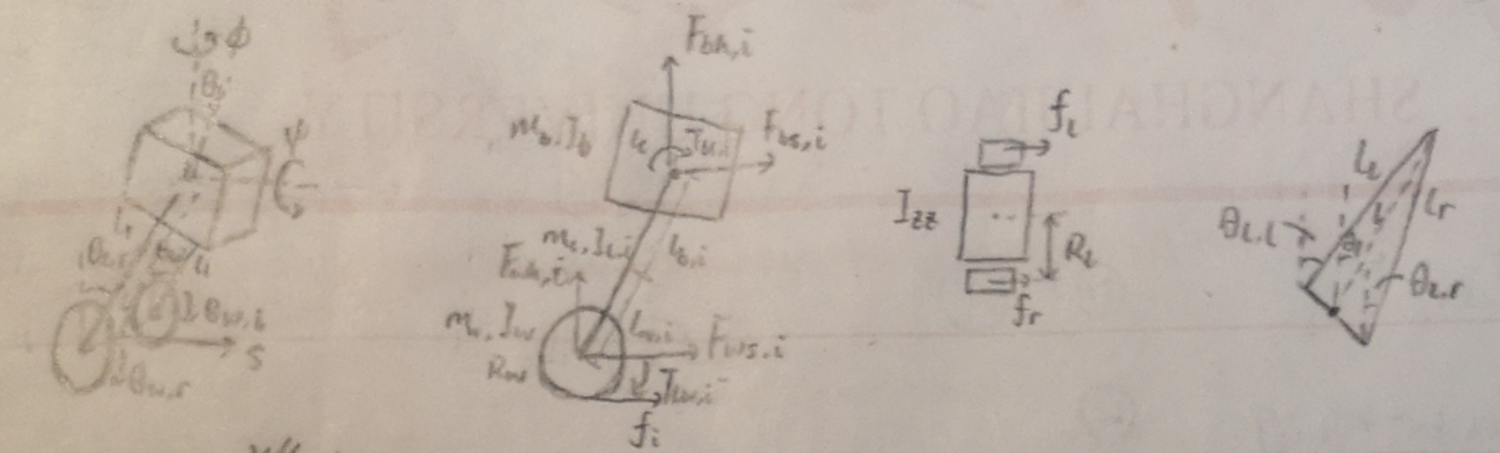

% theta_wl  :   左轮转角(独立变量)            theta_wr  :   右轮转角(独立变量)
% theta_ll  :   左腿与竖直夹角(独立变量)       theta_lr  :   右腿与竖直夹角(独立变量)
% theta_b   :   机体与竖直方向夹角(独立变量)   phi       :   偏航角(yaw)（上往下看逆时针为正）

% s         :   机器人水平移动距离
% s_b       :   机体质心水平移动距离     h_b     :   自然坐标系，机体质心竖直移动距离
% s_ll      :   左腿质心水平移动距离     s_lr    :   右腿质心水平移动距离 
% h_ll      :   左腿质心竖直移动距离     h_lr    :   右腿质心竖直移动距离 

% T_wl      :   左轮扭矩(独立变量)       T_wr    :   右轮扭矩(独立变量)
% T_bl      :   左腿扭矩(独立变量)       T_br    :   右腿扭矩(独立变量)

% f_l       :   左轮摩擦力              f_r     :   右轮摩擦力

% F_wsl     :   左轮对腿水平作用力       F_wsr   :   右轮对腿水平作用力
% F_whl     :   左轮对腿竖直作用力       F_whr   :   右轮对腿竖直作用力

% F_bsl     :   左腿对机体水平作用力     F_bsr   :   右腿对机体水平作用力
% F_bhl     :   左腿对机体竖直作用力     F_bhr   :   右腿对机体竖直作用力

###     2、参数的定义

% R_w   :   轮子半径              R_l   :   轮间距/2

% l_l   :   左腿长                l_r   :   右腿长
% l_wl  :   左轮轴到腿质心距离     l_wr  :   右轮轴到腿质心距离
% l_bl  :   左腿质心到髋部距离     l_br  :   右腿质心到髋部距离
% l_c   :   机体质心到髋关节距离

% m_w   :   轮子质量              
% m_l   :   腿部质量        
% m_b   :   机体质量  

% I_w   :   轮子转动惯量
% I_ll  :   左腿转动惯量          I_lr  :   右腿转动惯量        
% I_z   :   机体z轴转动惯量*2     I_b   :   机体pitch转动惯量

% g     :   重力加速度

## 三、列方程求解A、B矩阵

clear;
clc;

####     1、变量与参数

%-----------------运动学变量-------------------%
syms theta_wl theta_wr theta_dot_wl theta_dot_wr theta_ddot_wl theta_ddot_wr
syms theta_ll(t) theta_lr(t) theta_b(t) phi(t) s(t) 

%-----------------动力学变量-------------------%
syms T_wl T_wr T_bl T_br

%-----------------参数-------------------%
syms l_l  l_r
% syms R_w  R_l 
% syms m_w m_l m_b  I_w I_ll I_lr I_b I_z  l_c  g

R_w = 0.06;     R_l = 0.2655;
m_b = 12.5;     m_l = 1.72;    m_w = 1.2;
I_z = 0.656283; l_c = 0.021;     g = 9.8;

l_wl = l_l/2;  l_wr = l_r/2;  % 轮轴到腿质心距离（质心认为是几何中心）
l_bl = l_l/2;  l_br = l_r/2;  % 腿质心到髋部距离（质心认为是几何中心）
I_b = m_b*(0.3^2+0.12^2)/12.0;
I_ll = m_l*( (l_l)^2+0.05^2 )/12.0;%腿部转动惯量1/12*m*L²
I_lr = m_l*( (l_r)^2+0.05^2 )/12.0;%腿部转动惯量1/12*m*L²
% I_w = 1/2*m_w*R_w^2; %把轮子视为圆柱体，转动惯量为1/2*质量*半径²（马老师这里没有1/2）
I_w = m_w*R_w^2;% 测试：去除1/2

####   2、运动学：根据变量、参数定义和几何关系得到系统的运动学方程，进而解得各变量的表达式

    解出$\theta_{wl}$和$\theta_{wr}$

% 2.1：水平位移 = 轮子半径*轮转角
eqn1 = s == R_w*(theta_wl+theta_wr)/2;

%{
% 2.5 2.6（由这两个方程推出2.7 2.8）
% 移项后
% 机体质心水平位移 = 轮半径*左轮转角 + 轮距/2*Yaw + 腿长*sin（腿部夹角）
% 机体质心水平位移 = 轮半径*右轮转角 - 轮距/2*Yaw + 腿长*sin（腿部夹角）
syms s_b
Temp_equ25 = R_w*theta_wl == s_b - R_l*phi - Leg_length_l*sin(theta_ll); 
Temp_equ26 = R_w*theta_wr == s_b + R_l*phi - Leg_length_r*sin(theta_lr);
[s_b,phi] = solve(Temp_equ25,Temp_equ26,s_b,yaw)
%}

% 联立2.5 2.6解得2.7 2.8
% 2.7 phi(偏航角yaw)
eqn2 = phi == R_w/(2*R_l)*(theta_wr-theta_wl)...
            - l_l/(2*R_l)*sin(theta_ll)...
            + l_r/(2*R_l)*sin(theta_lr);

[theta_wl,theta_wr] = solve(eqn1,eqn2,theta_wl,theta_wr);

解出${\dot{\theta} }_{wl}$和${\dot{\theta} }_{wr}$

% 2.8 s_b
s_b = R_w/2*(theta_wl+theta_wr) ...
    + l_l/2*sin(theta_ll)...
    + l_r/2*sin(theta_lr);

% 2.9 速度 = 轮半径 * 轮速度 (对2.1求一导)
eqn3 = diff(s,t,1) == R_w/2*(theta_dot_wl + theta_dot_wr);

% 2.11 偏航角速度 (对2.7求一导)
eqn4 = diff(phi,t,1) == R_w/(2*R_l)*(theta_dot_wr - theta_dot_wl)...
                -l_l/(2*R_l)*cos(theta_ll)*diff(theta_ll,t,1)...
                +l_r/(2*R_l)*cos(theta_lr)*diff(theta_lr,t,1);

[theta_dot_wl,theta_dot_wr] = solve(eqn3,eqn4,theta_dot_wl,theta_dot_wr);

解出${\ddot{\theta} }_{wl}$和${\ddot{\theta} }_{wr}$

% 2.10 加速度 = 轮半径 * 轮加速度 (对2.1求二导)
eqn5 = diff(s,t,2) == R_w/2*(theta_ddot_wl + theta_ddot_wr);

% 2.12 偏航角加速度 (对2.7求二导)
eqn6 = diff(phi,t,2) == R_w/(2*R_l)*(theta_ddot_wr - theta_ddot_wl) ...
                       - l_l/(2*R_l)*cos(theta_ll)*diff(theta_ll,t,2) ...
                       + l_r/(2*R_l)*cos(theta_lr)*diff(theta_lr,t,2) ...
                       + l_l/(2*R_l)*sin(theta_ll)*(diff(theta_ll,t,1))^2 ...
                       - l_r/(2*R_l)*sin(theta_lr)*(diff(theta_lr,t,1))^2;

[theta_ddot_wl,theta_ddot_wr] = solve(eqn5,eqn6,theta_ddot_wl,theta_ddot_wr);

其他运动学方程

% 2.2：机体质心竖直位移 = ( 左腿长*cos(左腿夹角) + 右腿长*cos(右腿夹角) )/2
% 以轮子中心为原点
h_b = ( l_l*cos(theta_ll) + l_r*cos(theta_lr) )/2; 

% 2.3：腿部质心水平位移 = 轮子半径*轮转角 + 轮轴到腿部质心距离*sin(腿部夹角)
s_ll = R_w*theta_wl + l_wl*sin(theta_ll);
s_lr = R_w*theta_wr + l_wr*sin(theta_lr);

% 2.4：（移项后变成）机体质心竖直位移 = 腿部质心竖直位移 + 腿质心到髋部距离*cos(腿部夹角)
h_ll = h_b - l_bl*cos(theta_ll);
h_lr = h_b - l_br*cos(theta_lr);

% 2.13 机体质心水平速度 (对2.8求一导)
s_dot_b = R_w/2*(theta_dot_wl + theta_dot_wr) ...
        + l_l/2*cos(theta_ll)*diff(theta_ll,t,1) ...
        + l_r/2*cos(theta_lr)*diff(theta_lr,t,1);

% 2.14 机体质心水平加速度 (对2.8求二导)
s_ddot_b = R_w/2*(theta_ddot_wl+theta_ddot_wr) ...
         + l_l/2*cos(theta_ll)*diff(theta_ll,t,2)...
         + l_r/2*cos(theta_lr)*diff(theta_lr,t,2) ...
         - l_l/2*sin(theta_ll)*(diff(theta_ll,t,1))^2 ...
         - l_r/2*sin(theta_lr)*(diff(theta_lr,t,1))^2;

% 2.15 机体质心竖直速度 (对2.2求一导)
h_dot_b = - l_l/2*sin(theta_ll)*diff(theta_ll,t,1) ...
          - l_r/2*sin(theta_lr)*diff(theta_lr,t,1);

% 2.16 机体质心竖直加速度 (对2.2求二导)
h_ddot_b=-l_l/2*sin(theta_ll)*diff(theta_ll,t,2)...
        -l_r/2*sin(theta_lr)*diff(theta_lr,t,2)...
        -l_l/2*cos(theta_ll)*(diff(theta_ll,t,1))^2-...
         l_r/2*cos(theta_lr)*(diff(theta_lr,t,1))^2;

% 2.17 腿部质心水平速度 (对2.3求一导)
s_dot_ll = R_w*theta_dot_wl + l_wl*cos(theta_ll)*diff(theta_ll,t,1);
s_dot_lr = R_w*theta_dot_wr + l_wr*cos(theta_lr)*diff(theta_lr,t,1);

% 2.18 腿部质心水平加速度 (对2.3求二导)
s_ddot_ll = R_w*theta_ddot_wl ...
          + l_wl*cos(theta_ll)*diff(theta_ll,t,2) ...
          - l_wl*sin(theta_ll)*(diff(theta_ll,t,1))^2;

s_ddot_lr = R_w*theta_ddot_wr ...
          + l_wr*cos(theta_lr)*diff(theta_lr,t,2) ...
          - l_wr*sin(theta_lr)*(diff(theta_lr,t,1))^2;

% 2.19 腿部质心竖直速度 (对2.4求一导)
h_dot_ll = h_dot_b + l_bl*sin(theta_ll)*diff(theta_ll,t,1);
h_dot_lr = h_dot_b + l_br*sin(theta_lr)*diff(theta_lr,t,1);

% 2.20 腿部质心竖直加速度 (对2.4求二导)
h_ddot_ll = h_ddot_b ...
          + l_bl*sin(theta_ll)*diff(theta_ll,t,2) ...
          + l_bl*cos(theta_ll)*(diff(theta_ll,t,1))^2;

h_ddot_lr = h_ddot_b ...
          + l_br*sin(theta_lr)*diff(theta_lr,t,2) ...
          + l_br*cos(theta_lr)*(diff(theta_lr,t,1))^2;

####    3、动力学：根据牛顿欧拉法建立方程

% 对于左右驱动轮 3.1 3.2
% syms f_l f_r F_wsl F_wsr
% Temp_equ31 = [...
% m_w*R_w*theta_ddot_wl == f_l - F_wsl,...  %左轮F=ma
% m_w*R_w*theta_ddot_wr == f_r - F_wsr,...  %右轮F=ma
% I_w*theta_ddot_wl == T_wl - f_l*R_w,...   %左轮Jα=M
% I_w*theta_ddot_wr == T_wr - f_r*R_w...    %右轮Jα=M
% ];
% [f_l,f_r,F_wsl,F_wsr] = solve(Temp_equ31,[f_l,f_r,F_wsl,F_wsr])

% 根据3.1 3.2解得
F_wsl = (T_wl - m_w*R_w^2*theta_ddot_wl - I_w*theta_ddot_wl)/R_w;
F_wsr = (T_wr - m_w*R_w^2*theta_ddot_wr - I_w*theta_ddot_wr)/R_w;
f_l = m_w*R_w*theta_ddot_wl + F_wsl;
f_r = m_w*R_w*theta_ddot_wr + F_wsr;

% 3.3（移项后变成）腿水平方向F=ma
F_bsl = F_wsl - m_l*s_ddot_ll;
F_bsr = F_wsr - m_l*s_ddot_lr;

% 3.4 3.7 3.10
% syms F_whl F_whr F_bhl F_bhr h_ddot_ll h_ddot_lr h_ddot_b
% Temp_equ32 = [ ...
% m_l*h_ddot_ll == F_whl - F_bhl - m_l*g, ... %左腿竖直方向F=ma
% m_l*h_ddot_lr == F_whr - F_bhr - m_l*g, ... %右腿竖直方向F=ma
%  m_b*h_ddot_b == F_bhl + F_bhr - m_b*g, ... %机体竖直方向F=ma
%         F_whl == F_whr ...                  %左右轮支持力相同
% ];
% [F_bhl,F_bhr,F_whl,F_whr] = solve (Temp_equ32,[F_bhl,F_bhr,F_whl,F_whr])

% 根据3.4 3.7 3.10解得
F_bhl = (m_b*h_ddot_b + m_b*g)/2 - (m_l*h_ddot_ll - m_l*h_ddot_lr)/2;
F_bhr = (m_b*h_ddot_b + m_b*g)/2 + (m_l*h_ddot_ll - m_l*h_ddot_lr)/2;
F_whl = m_l*h_ddot_ll + m_l*g + F_bhl;
F_whr = m_l*h_ddot_lr + m_l*g + F_bhr;

% 3.5 腿部 M=Jα
equation1 = I_ll*diff(theta_ll,t,2) == (F_whl*l_wl + F_bhl*l_bl)*sin(theta_ll)...
                                     - (F_wsl*l_wl + F_bsl*l_bl)*cos(theta_ll) ...
                                     - T_wl + T_bl;
equation2 = I_lr*diff(theta_lr,t,2) == (F_whr*l_wr + F_bhr*l_br)*sin(theta_lr)...
                                     - (F_wsr*l_wr + F_bsr*l_br)*cos(theta_lr) ...
                                     - T_wr + T_br;

% 3.6 机体水平F=ma
equation3 = F_bsl + F_bsr == m_b*s_ddot_b;

% 3.8 机体pitch轴 M=Jα
% (马老师的文件中前两个符号为+，但是上交的开源文件中前两个符号是-。
% 因为马老师定义的pitch是与水平的夹角。上交是与竖直的夹角，实际情况看机器人上是怎么定的
% 上交写法
% equation4 = I_b*diff(theta_b,t,2) == - (T_bl + T_br) ...
%                                      - (F_bsl + F_bsr)*l_c*cos(theta_b) ...
%                                      + (F_bhl + F_bhr)*l_c*sin(theta_b);
% 马老师写法
equation4 = I_b*diff(theta_b,t,2) == + (T_bl + T_br) ...
                                     + (F_bsl + F_bsr)*l_c*cos(theta_b) ...
                                     + (F_bhl + F_bhr)*l_c*sin(theta_b);


% 3.9 机体yaw旋转J=Mα
equation5 = I_z*diff(phi,t,2) == (f_r - f_l)*R_l;

#### 3、求解

    将式 (2.1)~(2.4)，(2.7)~(2.20) 代入式 (3.1)~(3.10) ，分析动力学方程组，共有15个未知量（5个广义坐标的二阶导数+10个约束力），15个独立方程（关于未知量线性），方程组有唯一解。

% 5个广义坐标：s phi theta_ll theta_lr theta_b
% 10个约束力：f_i  F_wsi  F_whi  F_bsi  F_bhi（i代表l或r）
syms s_ddot s_dot phi_ddot phi_dot theta_ddot_b theta_dot_b
syms theta_ddot_ll theta_dot_ll theta_ddot_lr theta_dot_lr
syms s0 phi0 theta_ll0 theta_lr0 theta_b0 

% 把几个关于时间的变量及其导数换成单独变量
% 原参数
Arr_Origin = {diff(s,t,2),        diff(s,t,1),        diff(phi,t,2),      diff(phi,t,1), ...
              diff(theta_ll,t,2), diff(theta_ll,t,1), diff(theta_lr,t,2), diff(theta_lr,t,1) ...
              diff(theta_b,t,2),  diff(theta_b,t,1),  s,                  phi, ...
              theta_ll,           theta_lr,           theta_b};
% 替换后的参数
Arr_Replace = {s_ddot,             s_dot,              phi_ddot,           phi_dot, ...
               theta_ddot_ll,      theta_dot_ll,       theta_ddot_lr,      theta_dot_lr, ...
               theta_ddot_b,       theta_dot_b,        s0,                 phi0, ...
               theta_ll0,          theta_lr0,          theta_b0};
% 替换
equation1 = subs(equation1, Arr_Origin, Arr_Replace);
equation2 = subs(equation2, Arr_Origin, Arr_Replace);
equation3 = subs(equation3, Arr_Origin, Arr_Replace);
equation4 = subs(equation4, Arr_Origin, Arr_Replace);
equation5 = subs(equation5, Arr_Origin, Arr_Replace);

消去约束力，并对腿部、机体倾角进行小角度近似，最后得到AB矩阵。

% 求解未知量
[s_ddot,phi_ddot,theta_ddot_ll,theta_ddot_lr,theta_ddot_b] ...
= solve(equation1,equation2,equation3,equation4,equation5, s_ddot,phi_ddot,theta_ddot_ll,theta_ddot_lr,theta_ddot_b);

% 设置状态向量，控制向量
X_Vector = [s0,   s_dot, phi0,   phi_dot, theta_ll0,   theta_dot_ll, theta_lr0,   theta_dot_lr, theta_b0,   theta_dot_b];
X_Vector_dot = [s_dot,s_ddot,phi_dot,phi_ddot,theta_dot_ll,theta_ddot_ll,theta_dot_lr,theta_ddot_lr,theta_dot_b,theta_ddot_b];
u_Vector = [T_wl,T_wr,T_bl,T_br];

% 求解雅各比矩阵
A = jacobian(X_Vector_dot, X_Vector); % X_dot关于X的雅各比矩阵
B = jacobian(X_Vector_dot, u_Vector); % X_dot关于u的雅各比矩阵

% 平衡点附近小角度近似
A = subs(A,{s_dot, phi_dot, theta_ll0, theta_dot_ll, theta_lr0, theta_dot_lr, ...
            theta_b0, theta_dot_b, T_wl, T_wr, T_bl, T_br}, ...
           {0,0,0,0,0,0,0,0,0,0,0,0});
B = subs(B,{s_dot, phi_dot, theta_ll0, theta_dot_ll, theta_lr0, theta_dot_lr, ...
            theta_b0, theta_dot_b, T_wl, T_wr, T_bl, T_br}, ...
           {0,0,0,0,0,0,0,0,0,0,0,0});

% 生成一个获取AB矩阵的函数（.m文件）
matlabFunction(A,B,'File', 'Func1_Get_AB_Matrix','Comments',['获取AB矩阵的函数，需要传入的参数是左右腿长，' ...
                                                      '由BalanceSoldier_LQR_ABMtrix生成 -- 创建者：林宸曳，25RM平步电控']);

% 测试一下生成的函数是否正确，传入两边腿长都是0.182m
[ATest,BTest] = Func1_Get_AB_Matrix(0.182,0.182)

ATest =          0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0  -12.1914         0  -12.1914         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0  -11.6119         0   11.6119         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0  180.3510         0   15.0475         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0   15.0475         0  180.3510         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000
         0         0         0         0   13.4928         0   13.4928         0   

BTest =          0         0         0         0
    3.7643    3.7643   -0.9614   -0.9614
         0         0         0         0
   -3.2139    3.2139   -0.9157    0.9157
         0         0         0         0
  -39.0069   -8.4468   14.2217    1.1866
         0         0         0         0
   -8.4468  -39.0069    1.1866   14.2217
         0         0         0         0
   -1.3371   -1.3371   10.2594   10.2594
